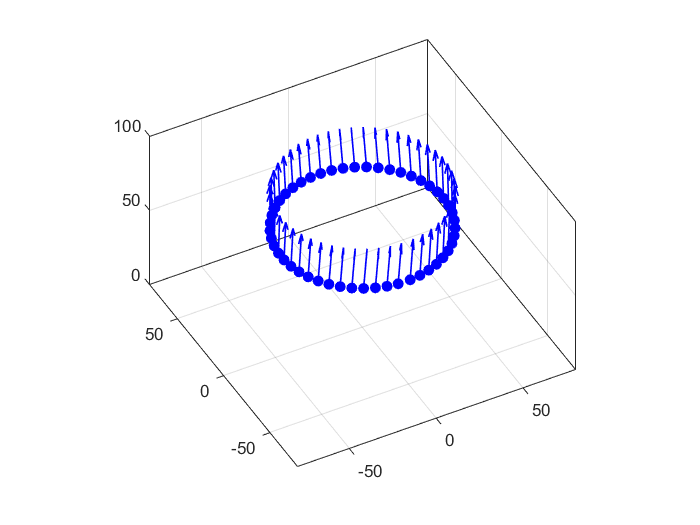

clear all
clc
load nov_12_xyza.mat
% generate the trajectory as a circle
c = 1;
circle_config = [];
circle_cartesian = [];

while c <= 50
    for c_delta_1 = deg2rad(1):deg2rad(359)/49:deg2rad(359) % define a circle consist of 50 points
        c_delta_2 = deg2rad(176);
        c_theta_1 = deg2rad(70);
        c_theta_2 = deg2rad(70);%pi/6;
        
        % position of the first segment
        c_px1(c) = (50*sin(c_delta_1)*cos(c_theta_1 + pi/2))/2;
        c_py1(c) = -(50*cos(c_delta_1)*cos(c_theta_1 + pi/2))/2;
        c_pz1(c) = 25 + (50*sin(c_theta_1 + pi/2))/2;
        % orientation of the first segment
        c_dir_alpha_Rx1(c) = sin(c_delta_1)*cos(c_theta_1 + pi/2);
        c_dir_beta_Rx1(c) = -cos(c_delta_1)*cos(c_theta_1 + pi/2);
        c_dir_gamma_Rx1(c) = sin(c_theta_1 + pi/2);
        c_dir_alpha_Ry1(c) = cos(c_delta_1);
        c_dir_beta_Ry1(c) =  sin(c_delta_1);
        c_dir_gamma_Ry1(c) =  0;
        c_dir_alpha_Rz1(c) = -sin(c_delta_1)*sin(c_theta_1 + pi/2);
        c_dir_beta_Rz1(c) = cos(c_delta_1)*sin(c_theta_1 + pi/2);
        c_dir_gamma_Rz1(c) = cos(c_theta_1 + pi/2);
        % position of the second segment
        c_px(c) = 50*sin(c_delta_1)*sin(c_theta_1) + 25*cos(c_theta_2 - pi/2)*(cos(c_delta_1)*sin(c_delta_2) + cos(c_delta_2)*sin(c_delta_1)*cos(c_theta_1)) - 25*sin(c_delta_1)*sin(c_theta_1)*sin(c_theta_2 - pi/2);
        c_py(c) = 25*cos(c_theta_2 - pi/2)*(sin(c_delta_1)*sin(c_delta_2) - cos(c_delta_1)*cos(c_delta_2)*cos(c_theta_1)) - 50*cos(c_delta_1)*sin(c_theta_1) + 25*cos(c_delta_1)*sin(c_theta_1)*sin(c_theta_2 - pi/2);
        c_pz(c) = 50*cos(c_theta_1) - 25*cos(c_theta_1)*sin(c_theta_2 - pi/2) - 25*cos(c_delta_2)*cos(c_theta_2 - pi/2)*sin(c_theta_1) + 25;
        % orientation of the second segment
        c_dir_alpha_Rx(c) = cos(c_theta_2 - pi/2)*(cos(c_delta_1)*sin(c_delta_2) + cos(c_delta_2)*sin(c_delta_1)*cos(c_theta_1)) - sin(c_delta_1)*sin(c_theta_1)*sin(c_theta_2 - pi/2);
        c_dir_beta_Rx(c) = cos(c_theta_2 - pi/2)*(sin(c_delta_1)*sin(c_delta_2) - cos(c_delta_1)*cos(c_delta_2)*cos(c_theta_1)) + cos(c_delta_1)*sin(c_theta_1)*sin(c_theta_2 - pi/2);
        c_dir_gamma_Rx(c) = - cos(c_theta_1)*sin(c_theta_2 - pi/2) - cos(c_delta_2)*cos(c_theta_2 - pi/2)*sin(c_theta_1);
        c_dir_alpha_Ry(c) = - sin(c_theta_2 - pi/2)*(cos(c_delta_1)*sin(c_delta_2) + cos(c_delta_2)*sin(c_delta_1)*cos(c_theta_1)) - sin(c_delta_1)*cos(c_theta_2 - pi/2)*sin(c_theta_1);
        c_dir_beta_Ry(c) =  cos(c_delta_1)*cos(c_theta_2 - pi/2)*sin(c_theta_1) - sin(c_theta_2 - pi/2)*(sin(c_delta_1)*sin(c_delta_2) - cos(c_delta_1)*cos(c_delta_2)*cos(c_theta_1));
        c_dir_gamma_Ry(c) =  cos(c_delta_2)*sin(c_theta_1)*sin(c_theta_2 - pi/2) - cos(c_theta_1)*cos(c_theta_2 - pi/2);
        c_dir_alpha_Rz(c) = cos(c_delta_1)*cos(c_delta_2) - sin(c_delta_1)*sin(c_delta_2)*cos(c_theta_1);
        c_dir_beta_Rz(c) = cos(c_delta_2)*sin(c_delta_1) + cos(c_delta_1)*sin(c_delta_2)*cos(c_theta_1);
        c_dir_gamma_Rz(c) = sin(c_delta_2)*sin(c_theta_1);
        
        % covert rotation matrices to euler angles (first segment)
        c_rot1 = [c_dir_alpha_Rx1(end,end) c_dir_alpha_Ry1(end,end) c_dir_alpha_Rz1(end,end);
            c_dir_beta_Rx1(end,end) c_dir_beta_Ry1(end,end) c_dir_beta_Rz1(end,end);
            c_dir_gamma_Rx1(end,end) c_dir_gamma_Ry1(end,end) c_dir_gamma_Rz1(end,end)];
        
        % covert rotation matrices to euler angles (second segment)
        c_rot = [c_dir_alpha_Rx(end,end) c_dir_alpha_Ry(end,end) c_dir_alpha_Rz(end,end);
            c_dir_beta_Rx(end,end) c_dir_beta_Ry(end,end) c_dir_beta_Rz(end,end);
            c_dir_gamma_Rx(end,end) c_dir_gamma_Ry(end,end) c_dir_gamma_Rz(end,end)];
        
        c_append_eul1 = rotm2eul(c_rot1);
        c_append_eul = rotm2eul(c_rot);
        
        % data preparation for the neural network
        c_append_config = [c_delta_1 c_theta_1 c_delta_2 c_theta_2];
        circle_config = [circle_config; c_append_config];
        c_append_cartesian = [c_px(c) c_py(c) c_pz(c)] + [0 0 -5];
        circle_cartesian = [circle_cartesian; c_append_cartesian c_append_eul];
        c = c+1;
    end
end

figure
plot3(c_px,c_py,c_pz,'o','Color','b','MarkerFaceColor','b');
hold on;
axis equal;
hx = quiver3(c_px,c_py,c_pz,c_dir_alpha_Rx,c_dir_beta_Rx,c_dir_gamma_Rx,'b','LineWidth',1,'AutoScaleFactor',2);
hold on;
%hy = quiver3(c_px,c_py,c_pz,c_dir_alpha_Ry,c_dir_beta_Ry,c_dir_gamma_Ry,'g','LineWidth',1,'AutoScaleFactor',2);
% hold on;
% hz = quiver3(c_px,c_py,c_pz,c_dir_alpha_Rz,c_dir_beta_Rz,c_dir_gamma_Rz,'b','LineWidth',1,'AutoScaleFactor',2);
% hold on;
axis([-80 80 -80 80 0 100]);
view([-28 41])
box on
hold on
grid on

% % plot orientation of the distal segment
% figure;
% hx = quiver3(c_px,c_py,c_pz,c_dir_alpha_Rx,c_dir_beta_Rx,c_dir_gamma_Rx,'r','LineWidth',1,'AutoScaleFactor',2);
% hold on;
% hy = quiver3(c_px,c_py,c_pz,c_dir_alpha_Ry,c_dir_beta_Ry,c_dir_gamma_Ry,'g','LineWidth',1,'AutoScaleFactor',2);
% hold on;
% hz = quiver3(c_px,c_py,c_pz,c_dir_alpha_Rz,c_dir_beta_Rz,c_dir_gamma_Rz,'b','LineWidth',1,'AutoScaleFactor',2);
% hold on;
% axis equal;
% box on;
% grid on;
% axis([-80 80 -80 80 0 100]);

% use the net to generate the predicted 4-D configration
predict_config = net(circle_cartesian');
predicted_config = predict_config'; %% to be used


% use the predicted circle configuration to calculate the actual cartesian
% position of the second segment
k = 1;
ae = [];
while k <=50
    delta_1 = predict_config(1,k);
    theta_1 = predict_config(2,k);
    delta_2 = predict_config(3,k);
    theta_2 = predict_config(4,k);
    
    px(k) = 50*sin(delta_1)*sin(theta_1) + 25*cos(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)) - 25*sin(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    py(k) = 25*cos(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1)) - 50*cos(delta_1)*sin(theta_1) + 25*cos(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    pz(k) = 50*cos(theta_1) - 25*cos(theta_1)*sin(theta_2 - pi/2) - 25*cos(delta_2)*cos(theta_2 - pi/2)*sin(theta_1) + 25;
    
    % orientation of the second segment
    dir_alpha_Rx(k) = cos( theta_2 - pi/2)*(cos( delta_1)*sin( delta_2) + cos( delta_2)*sin( delta_1)*cos( theta_1)) - sin( delta_1)*sin( theta_1)*sin( theta_2 - pi/2);
    dir_beta_Rx(k) = cos( theta_2 - pi/2)*(sin( delta_1)*sin( delta_2) - cos( delta_1)*cos( delta_2)*cos( theta_1)) + cos( delta_1)*sin( theta_1)*sin( theta_2 - pi/2);
    dir_gamma_Rx(k) = - cos( theta_1)*sin( theta_2 - pi/2) - cos( delta_2)*cos( theta_2 - pi/2)*sin( theta_1);
    dir_alpha_Ry(k) = - sin( theta_2 - pi/2)*(cos( delta_1)*sin( delta_2) + cos( delta_2)*sin( delta_1)*cos( theta_1)) - sin( delta_1)*cos( theta_2 - pi/2)*sin( theta_1);
    dir_beta_Ry(k) =  cos( delta_1)*cos( theta_2 - pi/2)*sin( theta_1) - sin( theta_2 - pi/2)*(sin( delta_1)*sin( delta_2) - cos( delta_1)*cos( delta_2)*cos( theta_1));
    dir_gamma_Ry(k) =  cos( delta_2)*sin( theta_1)*sin( theta_2 - pi/2) - cos( theta_1)*cos( theta_2 - pi/2);
    dir_alpha_Rz(k) = cos( delta_1)*cos( delta_2) - sin( delta_1)*sin( delta_2)*cos( theta_1);
    dir_beta_Rz(k) = cos( delta_2)*sin( delta_1) + cos( delta_1)*sin( delta_2)*cos( theta_1);
    dir_gamma_Rz(k) = sin( delta_2)*sin( theta_1);
    
    rot = [ dir_alpha_Rx(end,end)  dir_alpha_Ry(end,end)  dir_alpha_Rz(end,end);
        dir_beta_Rx(end,end)  dir_beta_Ry(end,end)  dir_beta_Rz(end,end);
        dir_gamma_Rx(end,end)  dir_gamma_Ry(end,end)  dir_gamma_Rz(end,end)];
    
    append_eul = rotm2eul( rot);
    ae = [ae;append_eul(1,2)];
    k = k+1;
end

% plot the actual cartesian
n = zeros(1,50);
n_98 = zeros(1,98)

n_98 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


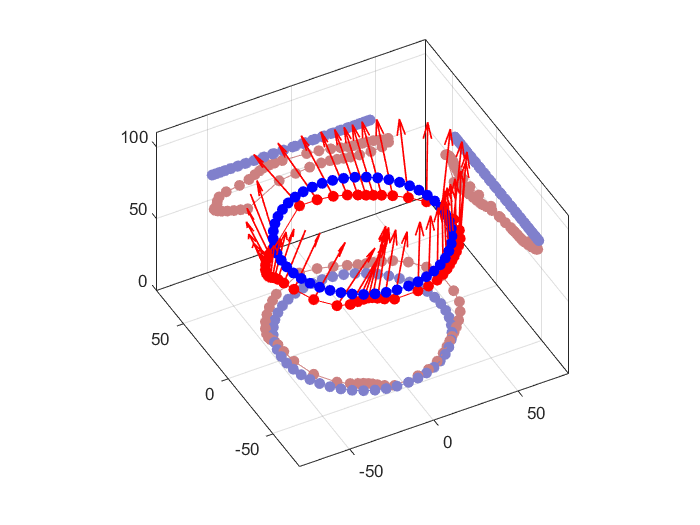

figure

plot3(px,py,pz,'o-','Color','r','MarkerFaceColor','r');
hold on
plot3(c_px,c_py,c_pz,'o-','Color','b','MarkerFaceColor','b');
axis equal;
axis([-80 80 -80 80 0 110]);
box on
hold on
grid on

plot3(px,py,n,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(c_px,c_py,n_98,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

plot3(px,n+80,pz,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(c_px,n_98+80,c_pz,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

plot3(n+80,py,pz,'o-','Color','[0.8 0.5 0.5]','MarkerFaceColor','[0.8 0.5 0.5]');
hold on
plot3(n_98+80, c_py,c_pz,'o-','Color','[0.5 0.5 0.8]','MarkerFaceColor','[0.5 0.5 0.8]');
hold on

hx_red = quiver3(px,py,pz,dir_alpha_Rx,dir_beta_Rx,dir_gamma_Rx,'r','LineWidth',1,'AutoScaleFactor',2);
hold on;

view([-28 41])

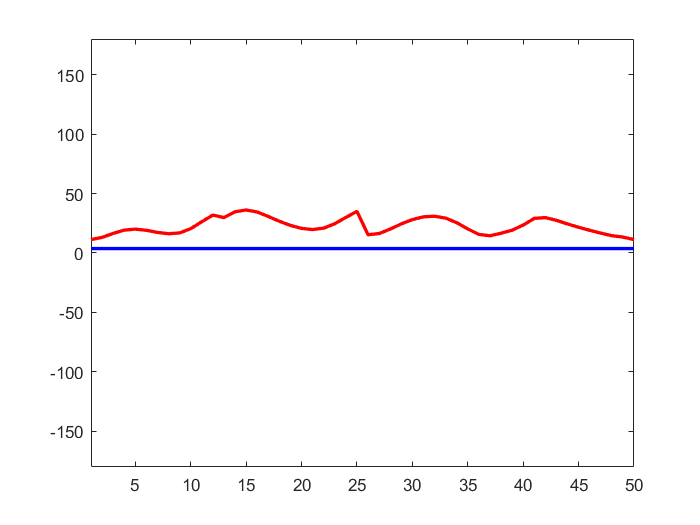

% figure
% plot(rad2deg(predicted_config(1:end,4)),'linewidth',2)
% axis([1 98 0 100])
figure
plot(rad2deg(circle_cartesian(1:50,5))+90,'linewidth',2,'color','b')
hold on
plot(rad2deg(ae)+90,'linewidth',2,'color','r')
axis([1 50 -180 180])

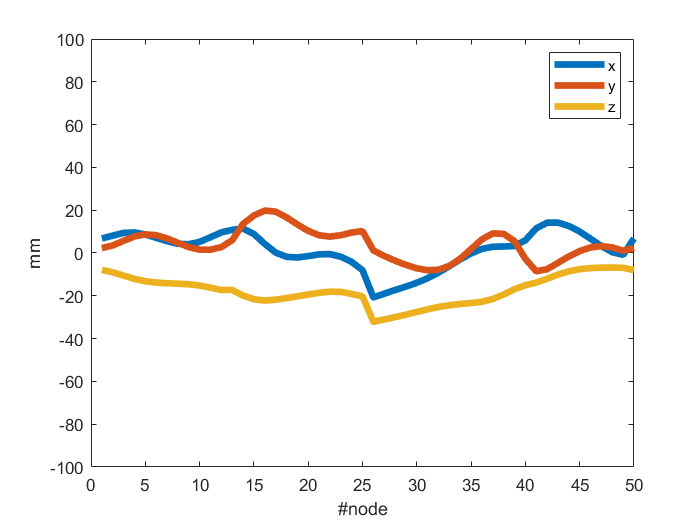

% generate some other shapes



figure

plot(px-c_px(1:50),'-','linewidth',4);hold on;

plot(py-c_py(1:50),'-','linewidth',4); hold on;
plot(pz-c_pz(1:50),'-','linewidth',4); hold on;
axis([0 50 -100 100])
legend('x','y','z')
xlabel('#node')
ylabel('mm')
box on